# **Scrip de teste**

### **Implementação do Método de Horner**

Para adicionar uma imagem fazemos imshow(imread('Imagen.jpg'))

%Teste da função MHorner

a=[3 1 1 1]; %3+x+x^2+x^3
x=-2:0.5:2;

tic %calcular tempo de execução do código
    y=MHorner(a, x);
    plot(x, y, 'or');
hold on
toc %fim do cornómetro

Elapsed time is 0.583821 seconds.



a=a(end:-1:1); %inverter para usar no polyval

tic
    y2=polyval(a, x);
    plot(x, y2, 'b');
toc

Elapsed time is 0.015772 seconds.


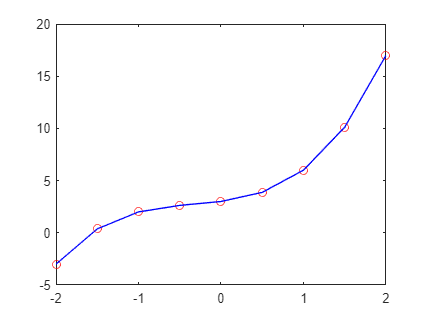

hold off


tabela=[x' y' y2'];
disp('Tabela Comparativa')

Tabela Comparativa



fprintf('\n\tx\tMHorner\tPolyval')


	x	MHorner	Polyval

disp(tabela)

   -2.0000   -3.0000   -3.0000
   -1.5000    0.3750    0.3750
   -1.0000    2.0000    2.0000
   -0.5000    2.6250    2.6250
         0    3.0000    3.0000
    0.5000    3.8750    3.8750
    1.0000    6.0000    6.0000
    1.5000   10.1250   10.1250
    2.0000   17.0000   17.0000

